## Lowpass filter in frequency domain

N=length(h1);
N_half=N/2;

% Frequency axis
k=1:N;                                          
f=(k-1)*(1/(N*ts));                   
f_c=f-((N-mod(N,2))/2)*(1/(N*ts));  

[signal_1_FFT, signal_2_FFT] = FFT(signal_1, signal_2);

#### Filter in frequency domain

filter_centered = zeros(1, N);
filter_centered(abs(f_c) <= cutoff_f) = 1 % Rectangle

filter_centered =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


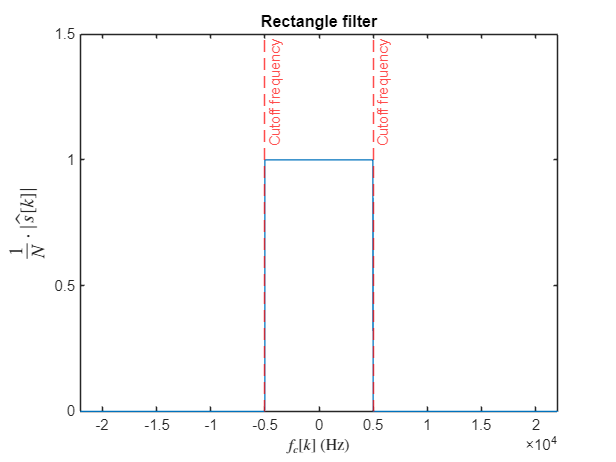

figure()
plot(f_c, filter_centered)
hold on
xline(-cutoff_f,LineStyle="--",Color='red',Label='Cutoff frequency')
xline(cutoff_f,LineStyle="--",Color='red',Label='Cutoff frequency')
ylim([0 1.5])
xlim([min(f_c) max(f_c)])
title('Rectangle filter');
xlabel('$f_c[k]$ (Hz)','Interpreter','Latex')
ylabel('$\frac{1}{N} \cdot |\hat{s}[k]|$','Interpreter','Latex', 'FontSize', 13)
hold off

filter_Notcentered = [filter_centered(N_half+1:end), filter_centered(1:N_half)];

filtered_signal_1_FFT = signal_1_FFT .* filter_Notcentered;
filtered_signal_2_FFT = signal_2_FFT .* filter_Notcentered;

#### Shift the end of the signal to the beginning

shifted_filtered_signal_1_FFT = [filtered_signal_1_FFT(N_half+1:end), filtered_signal_1_FFT(1:N_half)];
shifted_filtered_signal_2_FFT = [filtered_signal_2_FFT(N_half+1:end), filtered_signal_2_FFT(1:N_half)];

shifted_filtered_signal_1_FFT_magnitude = 1/N*abs(shifted_filtered_signal_1_FFT);
shifted_filtered_signal_2_FFT_magnitude = 1/N*abs(shifted_filtered_signal_2_FFT); 

#### Plot the DFT, recursive FFT and Matlab calculated FFT

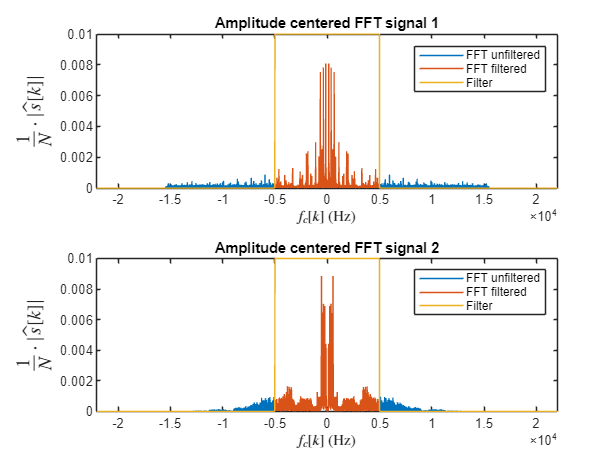

figure;
tiledlayout(2,1)
nexttile
plot(f_c, shifted_FFT_signal_1_magnitude);
hold on
plot(f_c, shifted_filtered_signal_1_FFT_magnitude);
plot(f_c, 0.01*(filter_centered))
hold off
title('Amplitude centered FFT signal 1');
xlabel('$f_c[k]$ (Hz)','Interpreter','Latex')
ylabel('$\frac{1}{N} \cdot |\hat{s}[k]|$','Interpreter','Latex', 'FontSize', 13)
legend('FFT unfiltered','FFT filtered','Filter')
xlim([min(f_c) max(f_c)])

nexttile
plot(f_c, shifted_FFT_signal_2_magnitude);
hold on
plot(f_c, shifted_filtered_signal_2_FFT_magnitude);
plot(f_c, 0.01*(filter_centered))
hold off
title('Amplitude centered FFT signal 2');
xlabel('$f_c[k]$ (Hz)','Interpreter','Latex')
ylabel('$\frac{1}{N} \cdot |\hat{s}[k]|$','Interpreter','Latex', 'FontSize', 13)
legend('FFT unfiltered','FFT filtered','Filter')
xlim([min(f_c) max(f_c)])

#### iFFT

[filtered_signal_1_iFFT, filtered_signal_2_iFFT] = iFFT(filtered_signal_1_FFT, filtered_signal_2_FFT);

#### Plot the iFFT and compare with the lowpassfiltered signal

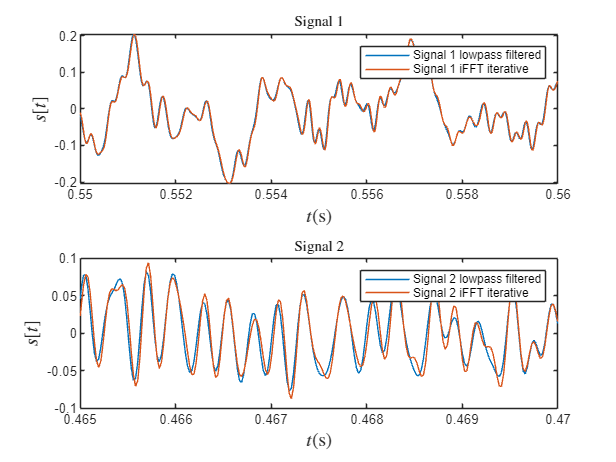

figure()
tiledlayout(2,1);
nexttile
plot(t-ts*n/2,h1)
hold on
plot(t,real(filtered_signal_1_iFFT))
hold off
title('Signal 1','Interpreter','Latex')
xlabel('$t$(s)','Interpreter','Latex', 'FontSize', 13)
ylabel('$s[t]$', 'Interpreter', 'latex', 'FontSize', 13);
legend('Signal 1 lowpass filtered','Signal 1 iFFT iterative')
xlim([0.55 0.56])%xlim([0 max(t)])

nexttile
plot(t-ts*n/2,h2)
hold on
plot(t,real(filtered_signal_2_iFFT))
hold off
title('Signal 2','Interpreter','Latex')
xlabel('$t$(s)','Interpreter','Latex', 'FontSize', 13)
ylabel('$s[t]$', 'Interpreter', 'latex', 'FontSize', 13);
legend('Signal 2 lowpass filtered','Signal 2 iFFT iterative')
xlim([0.465 0.47])%xlim([0 max(t)])

## Lowpass filter with convolution in time domain

#### Filterkernel

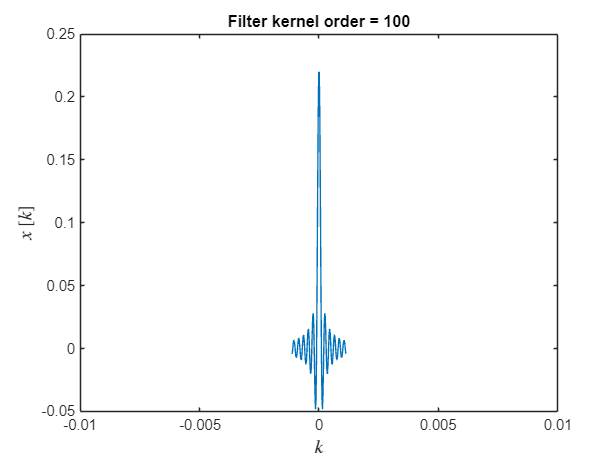

n=100;                      % Order
Idx = -(n-1)/2 : (n-1)/2;   % Symmetric indexing
t_filt = Idx / fs;           

filter_kernel = 2*cutoff_f*sinc(2*cutoff_f*t_filt); % Filterkern

filter_kernel = filter_kernel / sum(filter_kernel); % Normierung

figure()
plot(t_filt,(filter_kernel))
title(['Filter kernel order = ' num2str(n)])
xlabel('$k$','Interpreter','Latex', 'FontSize', 13);
ylabel('$x$ [$k$]','Interpreter','Latex', 'FontSize', 13);
xlim([-0.01 0.01])

#### Zero padding

F = length(signal_1) % Length signal

F = 65536

G = length(filter_kernel) % Length filter

G = 100

L = F + G - 1 % Resulting length

L = 65635

pad_start = floor(G / 2);
pad_end = ceil(G / 2) - 1;

signal_1_padded = [zeros(1, pad_start), signal_1, zeros(1, pad_end)];
signal_2_padded = [zeros(1, pad_start), signal_2, zeros(1, pad_end)];

filter_kernel_padded = [filter_kernel, zeros(1, L - G)];

#### Convolution in time domain

filtered_signal_1 = zeros(1, L);
filtered_signal_2 = zeros(1, L);

for l = 1:L
    for g = 1:G
        if l - g + 1 > 0
            filtered_signal_1(l) = filtered_signal_1(l) + signal_1_padded(l - g + 1) * filter_kernel_padded(g);
            filtered_signal_2(l) = filtered_signal_2(l) + signal_2_padded(l - g + 1) * filter_kernel_padded(g);
        end
    end
end

filtered_signal_1 = filtered_signal_1(G:G-1+F);
filtered_signal_2 = filtered_signal_2(G:G-1+F);

#### Plot the convoluted signal with the frequenzy domain filtered and with the lowpassfiltered signal

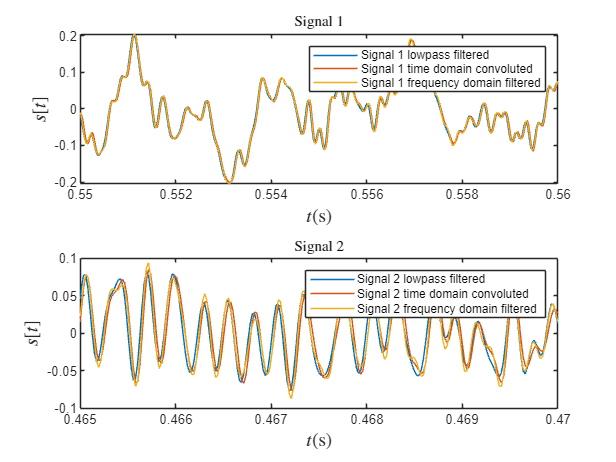

figure()
tiledlayout(2,1);
nexttile
plot(t-ts*n/2,h1)
hold on
plot(t,filtered_signal_1)
plot(t,real(filtered_signal_1_iFFT))
hold off
title('Signal 1','Interpreter','Latex')
xlabel('$t$(s)','Interpreter','Latex', 'FontSize', 13)
ylabel('$s[t]$', 'Interpreter', 'latex', 'FontSize', 13);
legend('Signal 1 lowpass filtered','Signal 1 time domain convoluted', 'Signal 1 frequency domain filtered')
xlim([0.55 0.56])%xlim([0 max(t)])

nexttile
plot(t-ts*n/2,h2)
hold on
plot(t,filtered_signal_2)
plot(t,real(filtered_signal_2_iFFT))
hold off
title('Signal 2','Interpreter','Latex')
xlabel('$t$(s)','Interpreter','Latex', 'FontSize', 13)
ylabel('$s[t]$', 'Interpreter', 'latex', 'FontSize', 13);
legend('Signal 2 lowpass filtered','Signal 2 time domain convoluted', 'Signal 2 frequency domain filtered')
xlim([0.465 0.47])%xlim([0 max(t)])

disp(['Comparison time domain filtered signal 1 and frequency domain filtered signal 1 // Difference = ' num2str(sum(filtered_signal_1-real(filtered_signal_1_iFFT)))])

Comparison time domain filtered signal 1 and frequency domain filtered signal 1 // Difference = -4.172e-15


disp(['Comparison time domain filtered signal 2 and frequency domain filtered signal 2 // Difference = ' num2str(sum(filtered_signal_2-real(filtered_signal_2_iFFT)))])

Comparison time domain filtered signal 2 and frequency domain filtered signal 2 // Difference = -0.021173
